clc;  
clear; 
Xmin = 1; 
Xmax =3; 
checking = -cos(Xmax)+cos(Xmin); 
 
N = 3

N = 3

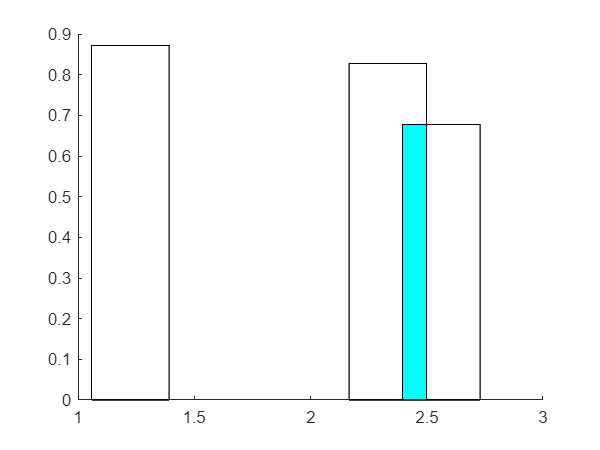

h = (Xmax-Xmin)/N; 
xx_1 = 1:0.01:3; 
f = @(x)sin(x); 
yy_1 = f(xx_1); 
 
xx_2 = zeros(1, N); 
yy_2 = zeros(1, N); 
 
xx_1_color = zeros(1, N); 

for i =1:N 
    xx_2(i) = Xmin+(Xmax-Xmin)*rand(); 
    yy_2(i) = f(xx_2(i)); 
    rectangle('Position', [xx_2(i), 0, h/2, yy_2(i)]);
    xlim([Xmin, Xmax]);
end 

for i =1:N
    for j = i+1:N
        if (abs(xx_2(i) - xx_2(j)) < h/2)
            rectangle('Position', [max(xx_2(i), xx_2(j)), 0, min(xx_2(i), xx_2(j)) + h/2 - max(xx_2(i), xx_2(j)), min(yy_2(j), yy_2(i))], 'FaceColor', '0, 1, 1')
        end
    end
end 
hold off;

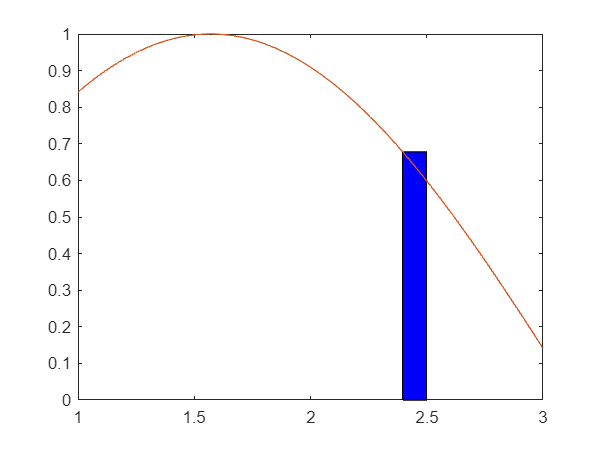



plot(xx_1, yy_1) 
for i = 1:N 
    for j = i+1:N 
        if (abs(xx_2(i) - xx_2(j)) < h/2) 
            if (xx_2(i)>xx_2(j)) 
                if (xx_1_color(i) == 0) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '0 0 1'); hold on 
                end 
                if  (xx_1_color(i) == 1) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '0 1 0'); hold on 
                end 
                if  (xx_1_color(i) == 2) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '1 0 0'); hold on 
                end 
                if  (xx_1_color(i) >= 2) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '1 1 0'); hold on 
                end 
                xx_1_color(i)= xx_1_color(i) +1; 
            end 
 
            if (xx_2(i)<xx_2(j)) 
                if (xx_1_color(j) == 0) 
                rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '0 0 1'); hold on 
                end 
                if  (xx_1_color(j) == 1) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '0 1 0'); hold on 
                end 
                if  (xx_1_color(j) == 2) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '1 0 0'); hold on 
                end 
                if  (xx_1_color(j) >= 2) 
                    rectangle('Position', [max(xx_2(i),xx_2(j)), 0, min(xx_2(i),xx_2(j))+h/2-max(xx_2(i),xx_2(j)), min(yy_2(i),yy_2(j))], 'FaceColor', '1 1 1'); hold on 
                end 
                xx_1_color(j)= xx_1_color(j) +1; 
            end 
        end 
    end 
end 
plot(xx_1,yy_1) 
 
hold off